clc;close all;clear all;
load("data\system_parameters.mat");
addpath('inc\')

## Statics

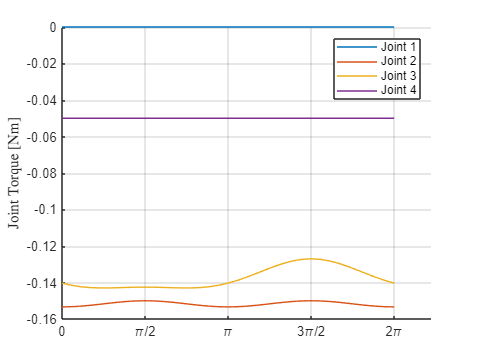

load("data\trajectory_jointSpace_discrete.mat")
F = [0;0;-1;0;0;0];
for i = 1:length(q)
    T = fwdKin(q(:,i),p);
    o4 = T.T40(1:3,4);
    tau(:,i) = jac(o4,T)'*F;
end

hold on
plot(0:2*pi/36:2*pi,tau);
xticks([0 pi/2 pi 3*pi/2 2*pi])
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'})
ylabel("Joint Torque [Nm]",'Interpreter','latex')
legend("Joint 1","Joint 2","Joint 3","Joint 4")
grid on